clc
clear all
close all
cost_matrix=[0,4,2,0,0,9;
            4,0,6,0,0,0 ;
            2,6,0,10,0,0;
            0,0,10,0,4,1;
            0,0,0,4,0,5;
            9,0,0,2,5,0;]

cost_matrix =      0     4     2     0     0     9
     4     0     6     0     0     0
     2     6     0    10     0     0
     0     0    10     0     4     1
     0     0     0     4     0     5
     9     0     0     2     5     0



s=size(cost_matrix)

s =      6     6


n=s(1)

n =      6


adj_matrix=zeros(n,n);

adj_matrix(cost_matrix ~= 0)=1

adj_matrix =      0     1     1     0     0     1
     1     0     1     0     0     0
     1     1     0     1     0     0
     0     0     1     0     1     1
     0     0     0     1     0     1
     1     0     0     1     1     0


C=zeros(n+1,n+1);
C(2:end, 2:end)=cost_matrix

C =      0     0     0     0     0     0     0
     0     0     4     2     0     0     9
     0     4     0     6     0     0     0
     0     2     6     0    10     0     0
     0     0     0    10     0     4     1
     0     0     0     0     4     0     5
     0     9     0     0     2     5     0


adj=zeros(n,n);

A=zeros(n+1,n+1);
A(2:end,1)=1;
A(1,2:end)=1;
A(2:end,2:end)=adj_matrix;
A

A =      0     1     1     1     1     1     1
     1     0     1     1     0     0     1
     1     1     0     1     0     0     0
     1     1     1     0     1     0     0
     1     0     0     1     0     1     1
     1     0     0     0     1     0     1
     1     1     0     0     1     1     0


sz=size(A)

sz =      7     7


n1=sz(1)

n1 =      7


m1=sz(2)

m1 =      7


aadhu= A(2:end,2:end)-tril(ones(6,6))%credits to aadharsh

aadhu =     -1     1     1     0     0     1
     0    -1     1     0     0     0
     0     0    -1     1     0     0
    -1    -1     0    -1     1     1
    -1    -1    -1     0    -1     1
     0    -1    -1     0     0    -1


[i,j]= find(aadhu==1)

i =      1
     1
     2
     3
     4
     1
     4
     5


j =      2
     3
     3
     4
     5
     6
     6
     6


i=i+1;
j=j+1;
t=optimproblem('ObjectiveSense','minimize');
F = optimvar('F',[n1,m1],'Type','integer','LowerBound',0,'UpperBound',1);
b = optimvar('b',[n1,m1],'Type','integer','LowerBound',0,'UpperBound',n1);

sum1=0;
for i1=1:n1
    for j1=i1:m1
        if(A(i1,j1)==1)
            sum1=sum1+C(i1,j1)*F(i1,j1)+C(i1,j1)*F(j1,i1);
        end
    end
end
t.Objective=sum1;
show(sum1);


  4*F(3, 2) + 2*F(4, 2) + 9*F(7, 2) + 4*F(2, 3) + 6*F(4, 3) + 2*F(2, 4) + 6*F(3, 4) + 10*F(5, 4) + 10*F(4, 5) + 4*F(6, 5) + F(7, 5) + 4*F(5, 6) + 5*F(7, 6)
+ 9*F(2, 7) + F(5, 7) + 5*F(6, 7)



c1=[]


c1 =

     []



for k=1:length(i)
    c1=[c1,F(i(k),j(k))+F(j(k),i(k))<=1];
end
t.Constraints.C1 = c1

t =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


sumi=0

sumi =      0


sumj=0

sumj =      0


Fc2=[]


Fc2 =

     []



Fc3=[]


Fc3 =

     []



for ci2=1:n1
    sumi=0;
    sumj=0;
    for cj2=1:m1
        if((A(ci2,cj2)==1) && (ci2~=cj2))
            sumi=sumi+F(ci2,cj2);
            sumj=sumj+F(cj2,ci2);
        end
    end
    Fc2=[Fc2,sumi==1];
    Fc3=[Fc3,sumj==1];
end
% 
t.Constraints.C2 = Fc2;
t.Constraints.C3 = Fc3;
 bc=[]


bc =

     []



for c3=2:n1
    bc=[bc,b(1,c3)==(n1-1)*F(1,c3);];
end
t.Constraints.C4 = bc ;
c5c=[];
c6c=[];  
for k=1:length(i)
    c5c=[c5c, b(i(k),j(k)) <= (n1-1)*F(i(k),j(k))];
    c6c=[c6c, b(j(k),i(k)) <= (n1-1)*F(j(k),i(k))];
end
t.Constraints.C5 = c5c;
t.Constraints.C6 = c6c;
Fc7=[]


Fc7 =

     []



for cj7=2:n1
    sumi7=0;
    sumj7=0;
    for ci7=1:m1
        if(A(ci7,cj7)==1)
            sumi7=sumi7+b(ci7,cj7);
            sumj7=sumj7+b(cj7,ci7);
        end
    end
    Fc7=[Fc7,sumi7-sumj7==1];
end

% bh=[b(1,2)+b(3,2)+b(4,2)+b(7,2)-b(2,1)-b(2,3)-b(2,4)-b(2,7)==1,
%     b(1,3)+b(2,3)+b(4,3)-b(3,1)-b(3,2)-b(3,4)==1,
%     b(1,4)+b(3,4)+b(2,4)+b(5,4)-b(4,1)-b(4,3)-b(4,2)-b(4,5)==1,
%     b(1,5)+b(4,5)+b(7,5)+b(6,5)-b(5,1)-b(5,4)-b(5,7)-b(5,6)==1,
%     b(1,6)+b(5,6)+b(7,6)-b(6,1)-b(6,5)-b(6,7)==1,
%     b(1,7)+b(5,7)+b(6,7)-b(7,1)-b(7,5)-b(7,6)==1];
t.Constraints.C7 =Fc7;
options = optimoptions('intlinprog')

options =   intlinprog options:

   Set properties:
     No options set.

   Default properties:
             AbsoluteGapTolerance: 0
                       BranchRule: 'reliability'
              ConstraintTolerance: 1.000000000000000e-04
                    CutGeneration: 'basic'
                 CutMaxIterations: 10
                          Display: 'iter'
                       Heuristics: 'basic'
               HeuristicsMaxNodes: 50
                IntegerPreprocess: 'basic'
                 IntegerTolerance: 1.000000000000000e-05
                  LPMaxIterations: 'max(30000,10*(numberOfEqualities+numberOfInequalities+numberOfVariables))'
            LPOptimalityTolerance: 1.000000000000000e-07
                MaxFeasiblePoints: Inf
                         MaxNodes: 10000000
                          MaxTime: 7200
                    NodeSelection: 'simplebestproj'
           

 sol = solve(t, 'Options',options)

Solving problem using intlinprog.
LP:                Optimal objective value is 16.500000.                                            

Cut Generation:    Applied 2 Gomory cuts,                                                           
                   7 implication cuts, 2 strong CG cuts,                                            
                   1 zero-half cut, and 2 flow cover cuts.                                          
                   Lower bound is 22.000000.                                                        

Heuristics:        Found 2 solutions using total rounding.                                          
                   Upper bound is 22.000000.                                                        
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective val

sol = struct with fields:
    F: [7×7 double]
    b: [7×7 double]


[sol,Fval]=solve(t);

Solving problem using intlinprog.
LP:                Optimal objective value is 16.500000.                                            

Cut Generation:    Applied 2 Gomory cuts,                                                           
                   7 implication cuts, 2 strong CG cuts,                                            
                   1 zero-half cut, and 2 flow cover cuts.                                          
                   Lower bound is 22.000000.                                                        

Heuristics:        Found 2 solutions using total rounding.                                          
                   Upper bound is 22.000000.                                                        
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective val

x1=sol.F

x1 =                    0                   0   0.999999999999999                   0                   0                   0                   0
                   0                   0                   0   1.000000000000001                   0                   0                   0
                   0   1.000000000000000                   0                   0                   0                   0                   0
                   0                   0                   0                   0   0.999999999999999                   0                   0
                   0                   0                   0                   0                   0                   0   1.000000000000000
   1.000000000000000                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0   1.000000000000000                   0


sol

sol = struct with fields:
    F: [7×7 double]
    b: [7×7 double]


Fval

Fval =   21.999999999999982


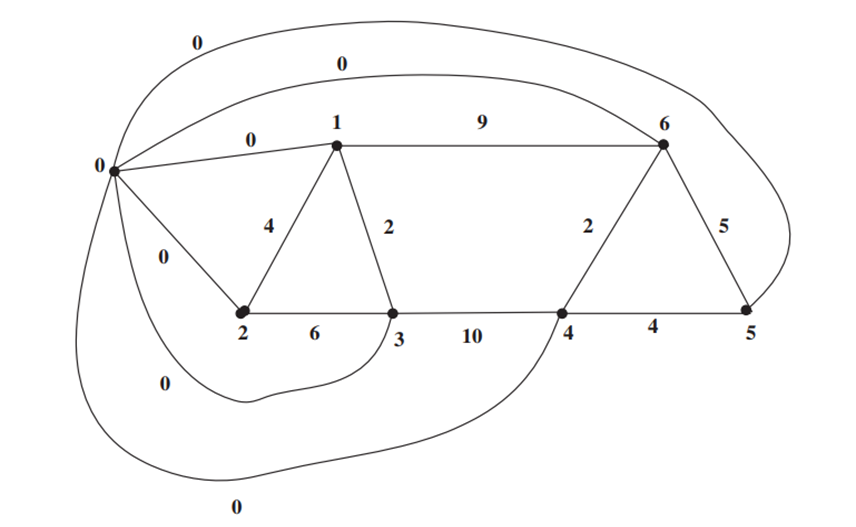

x2=sol.b

x2 =                    0                   0   5.999999999999991                   0                   0                   0                   0
                   0                   0                   0   4.000000000000000                   0                   0                   0
                   0   5.000000000000000                   0                   0                   0                   0                   0
                   0                   0                   0                   0   3.000000000000001                   0                   0
                   0                   0                   0                   0                   0                   0   2.000000000000000
                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0   1.000000000000000                   0


A

A =      0     1     1     1     1     1     1
     1     0     1     1     0     0     1
     1     1     0     1     0     0     0
     1     1     1     0     1     0     0
     1     0     0     1     0     1     1
     1     0     0     0     1     0     1
     1     1     0     0     1     1     0
